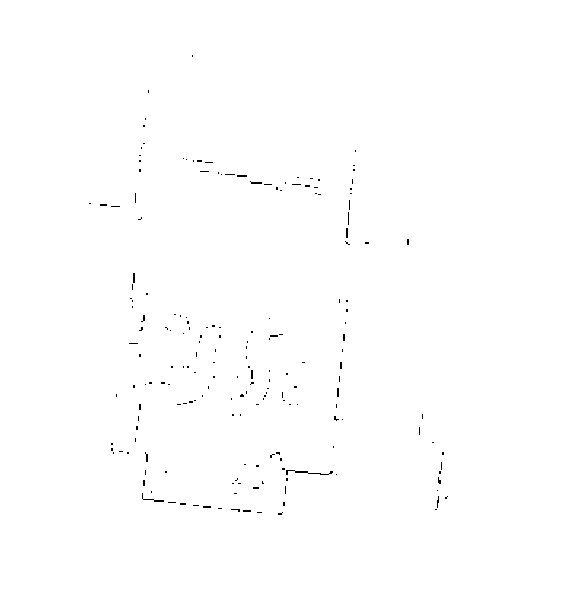

Ic = imread('hall_common_01.png'); % Read image
I = double(im2gray(Ic)); % Convert to grayscale image
% I = imbinarize(I_gray);
imshow(I);

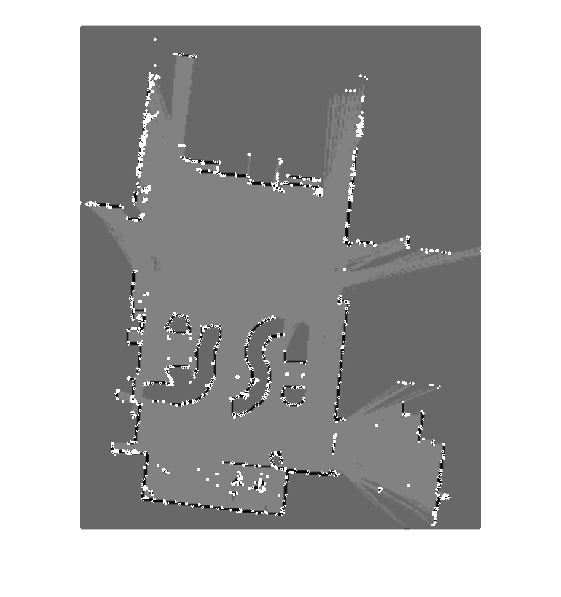

Ix = imfilter(I, [1 0 -1]); % Horizontal gradients
Iy = imfilter(I, [1 0 -1]'); % Vertical gradients
Ixx = Ix.*Ix;
Iyy = Iy.*Iy;
Ixy = Ix.*Iy;
A = imfilter(Ixx, ones(3)); % Sum Ixx in a 3x3 window
B = imfilter(Iyy, ones(3)); % Sum Iyy in a 3x3 window
C = imfilter(Ixy, ones(3)); % Sum Ixy in a 3x3 window
k = 0.06;
R = (A.*B-C.^2)-k*(A+B).^2;
R = R/max(max(R)); % Normalize R
figure, imshow(double(I/500+((R > 0.05)*100))); % 0.05 is a threshold